clear

subject.testNr = '0';
f2aim = [500:500:1500 2000:1000:10000].';
f2IdxSuper{1} = [2 4 6 10; 3 5 8 0; 1 7 12 0];
f2IdxSuper{2} = [2 4 6; 3 5 8; 1 7 12];
% f2Idx = [2 4 6; 3 5 8; 1 7 12; 10 0 0];

subject.folderLocation = ['Measurement/testPerson_' subject.testNr];
mkdir(subject.folderLocation)

% Right ear

subject.ear = ['tp_' subject.testNr '_right'];
mkdir([subject.folderLocation '/' subject.ear]);

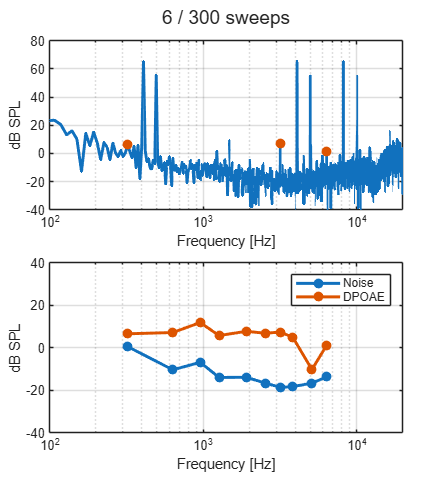

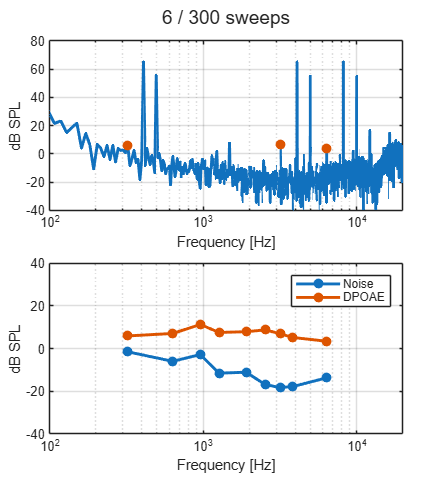


numRecs = length(f2IdxSuper);
measurementTimeMatrix = zeros(numRecs, 2);
for k = 1:numRecs
    f2Idx = f2IdxSuper{k};
    save("dpFrequenciesDummy.mat", "f2aim", "f2Idx");
    measMFDPOA;
    measurementTimeMatrix(k, 1) = measurementTime;
    clearvars -except f2IdxSuper f2aim numRecs measurementTimeMatrix subject
end

% Left ear

subject.ear = ['tp_' subject.testNr '_left'];
mkdir([subject.folderLocation '/' subject.ear]);

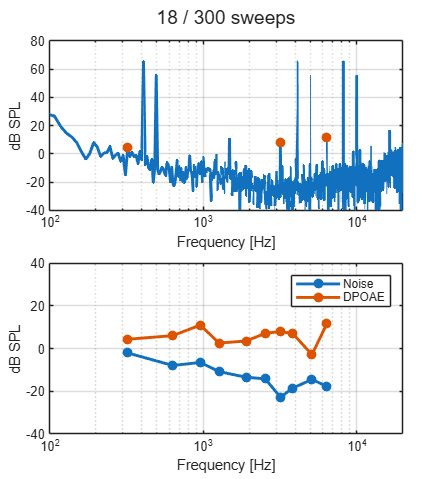

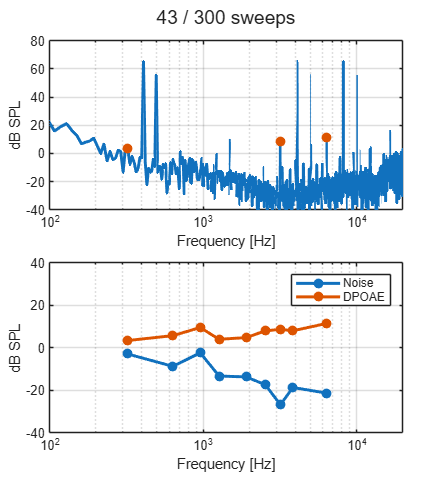


numRecs = length(f2IdxSuper);
measurementTimeMatrix = zeros(numRecs, 2);
for k = 1:numRecs
    f2Idx = f2IdxSuper{k};
    save("dpFrequenciesDummy.mat", "f2aim", "f2Idx");
    measMFDPOA;
    measurementTimeMatrix(k, 1) = measurementTime;
    clearvars -except f2IdxSuper f2aim numRecs measurementTimeMatrix subject
end


save([subject.folderLocation '/measurementTimes'], "measurementTimeMatrix");